clear
close all
rehash path

addpath ../sandbox

addpath ../bear

percentiles = [10, 50, 90];
prctileFunc = @(x) prctile(x, percentiles, 2);
firstFunc = @(x) x(:, 1, :, :, :);
medianFunc = @(x) median(x, 2);
flatFunc = @(x) x(:, :);
extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];
defaultColors = get(0, "defaultAxesColorOrder");

configStruct = json.read("testConfig_UK.json");
config = bear6.Config(configStruct);

config;

inputTbx = tablex.fromCsv("exampleData_repl_uk.csv");

meta = model.Meta( ...
    endogenous=config.Meta_EndogenousConcepts, ...
    units=config.Meta_Units, ...
    exogenous=config.Meta_ExogenousNames, ...
    order=config.Meta_Order, ...
    intercept=config.Meta_HasIntercept, ...
    estimationSpan=config.Meta_EstimationSpan, ...
    ...
    identificationHorizon=config.Meta_IdentificationHorizon, ...
    shockConcepts=config.Meta_ShockConcepts ...
);
meta;

dataH = model.DataHolder(meta, inputTbx);
dataH;

estimatorR = estimator.Minnesota( ...
    meta, ...
    config.Estimator_Settings{:} ...
);
estimatorR;

minnesotaD = dummies.Minnesota(exogenousLambda=100,lambda = 0.16,lagDecay=1, exogenous=true, autoregression = 0.3);
initialD = dummies.InitialObservations(lambda = 0.001);
longrunD = dummies.LongRun(lambda=1);
sumcoefD = dummies.SumCoefficients(lambda=0.1)

sumcoefD =   SumCoefficients with properties:

    Lambda: 0.1000


modelR = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR ...
    , dummies={minnesotaD, initialD, sumcoefD} ...
    , stabilityThreshold=Inf ...
);

modelR.initialize();
modelR;



return

modelR.presample(3000);

 Presampling model.ReducedForm (Minnesota) [3000]
 ―――――――――――――――――――――――――――――――――――――――――――――――――◼  100% 



modelR;

residTbx = modelR.estimateResiduals();
fcastStart = datex.shift(modelR.Meta.EstimationEnd, +1);
fcastEnd = datex.shift(modelR.Meta.EstimationEnd, +14);
fcastSpan = datex.span(fcastStart, fcastEnd);

fcastStart, fcastEnd

fcastStart = datetime
   2024-Q3


fcastEnd = datetime
   2027-Q4


fcastTbx = modelR.forecast(fcastSpan);
fcastTbx

fcastTbx = 16×16 timetable
     Time          Y_UK             P_UK             I_UK            NEER_UK             Y                P                I               OIL          resid_Y_UK       resid_P_UK       resid_I_UK      resid_NEER_UK       resid_Y          resid_P          resid_I         resid_OIL  
    _______    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________


fcastPrctileTbx = tablex.apply(fcastTbx, prctileFunc);
fcastPrctileTbx

fcastPrctileTbx = 16×16 timetable
     Time                  Y_UK                                P_UK                               I_UK                          NEER_UK                             Y                                   P                                 I                              OIL                              resid_Y_UK                               resid_P_UK                              resid_I_UK                            resid_NEER_UK                            resid_Y                                resid_P                                   resid_I                                resid_OIL            
    _______    _____________________________

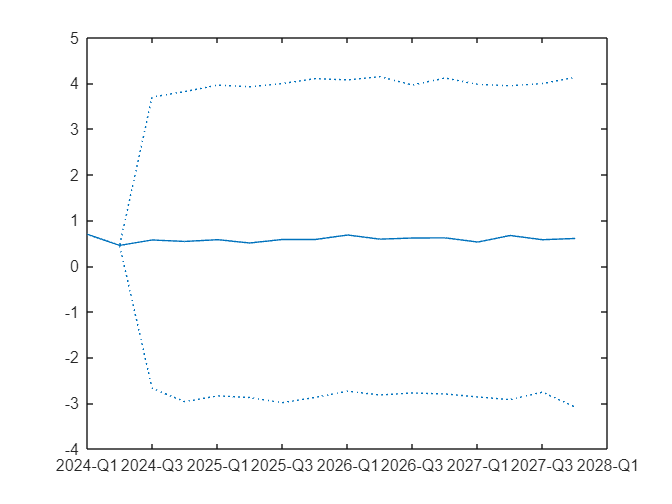


tablex.plot( ...
    fcastPrctileTbx, "Y_UK", ...
    plotSettings={"color", defaultColors(1, :), {"lineStyle"}, {":"; "-"; ":"}} ...
);

%Instant zeros
exactZerosTbx = tablex.forExactZeros(modelR);

%Domestic demand
exactZerosTbx{"Y", "DD"} = 0;
exactZerosTbx{"P", "DD"} = 0;
exactZerosTbx{"I", "DD"} = 0;
exactZerosTbx{"OIL", "DD"} = 0;
%Domestic supply
exactZerosTbx{"Y", "DS"} = 0;
exactZerosTbx{"P", "DS"} = 0;
exactZerosTbx{"I", "DS"} = 0;
exactZerosTbx{"OIL", "DS"} = 0;
%Domestic MP
exactZerosTbx{"Y", "DMP"} = 0;
exactZerosTbx{"P", "DMP"} = 0;
exactZerosTbx{"I", "DMP"} = 0;
exactZerosTbx{"OIL", "DMP"} = 0;
%Unidentified
exactZerosTbx{"Y", "UD"} = 0;
exactZerosTbx{"P", "UD"} = 0;
exactZerosTbx{"I", "UD"} = 0;
exactZerosTbx{"OIL", "UD"} = 0;

exactZerosTbx

exactZerosTbx = 8×8 table
               DD     DS     DMP    UD     FD     FS     FMP    OIL
               ___    ___    ___    ___    ___    ___    ___    ___

    Y_UK       NaN    NaN    NaN    NaN    NaN    NaN    NaN    NaN
    P_UK       NaN    NaN    NaN    NaN    NaN    NaN    NaN    NaN
    I_UK       NaN    NaN    NaN    NaN    NaN    NaN    NaN    NaN
    NEER_UK    NaN    NaN    NaN    NaN    NaN    NaN    NaN    NaN
    Y            0      0      0      0    NaN    NaN    NaN    NaN
    P            0      0      0      0    NaN    NaN    NaN    NaN
    I            0      0      0      


identExactZeros = identifier.ExactZeros(exactZerosTbx);
identExactZeros

identExactZeros =   ExactZeros with properties:

    RestrictionTable: [8×8 table]
     NumRestrictions: 16
             Sampler: []
       SampleCounter: 0
          Candidator: []
    CandidateCounter: 0
     BeenInitialized: 0
      ShortClassName: 'ExactZeros'


rng(0);

testStrings = [
    %Domestic demand
    "$SHKRESP(1, 'Y_UK', 'DD') > 0"
    "$SHKRESP(1, 'P_UK', 'DD') > 0"
    "$SHKRESP(1, 'I_UK', 'DD') > 0"
    %Domestic supply
    "$SHKRESP(1, 'Y_UK', 'DS') < 0"
    "$SHKRESP(1, 'P_UK', 'DS') > 0"
    %Dom MP
    "$SHKRESP(1, 'Y_UK', 'DMP') < 0"
    "$SHKRESP(1, 'P_UK', 'DMP') < 0"
    "$SHKRESP(1, 'I_UK', 'DMP') > 0"
    %Foreign demand
    "$SHKRESP(1, 'Y', 'FD') > 0"
    "$SHKRESP(1, 'P', 'FD') > 0"
    "$SHKRESP(1, 'I', 'FD') > 0"
    "$SHKRESP(1, 'OIL', 'FD') > 0"
    %Foreign supply
    "$SHKRESP(1, 'Y', 'FS') < 0"
    "$SHKRESP(1, 'P', 'FS') > 0"
    "$SHKRESP(1, 'OIL', 'FS') < 0"
    %Foreign MP
    "$SHKRESP(1, 'Y', 'FMP') < 0"
    "$SHKRESP(1, 'P', 'FMP') < 0"
    "$SHKRESP(1, 'I', 'FMP') > 0"
    %Oil
    "$SHKRESP(1, 'Y', 'OIL') < 0"
    "$SHKRESP(1, 'P', 'OIL') > 0"
    "$SHKRESP(1, 'OIL', 'OIL') > 0"
]

testStrings = 21×1 string array
    "$SHKRESP(1, 'Y_UK', 'DD') > 0"
    "$SHKRESP(1, 'P_UK', 'DD') > 0"
    "$SHKRESP(1, 'I_UK', 'DD') > 0"
    "$SHKRESP(1, 'Y_UK', 'DS') < 0"
    "$SHKRESP(1, 'P_UK', 'DS') > 0"
    "$SHKRESP(1, 'Y_UK', 'DMP') < 0"
    "$SHKRESP(1, 'P_UK', 'DMP') < 0"
    "$SHKRESP(1, 'I_UK', 'DMP') > 0"
    "$SHKRESP(1, 'Y', 'FD') > 0"
    "$SHKRESP(1, 'P', 'FD') > 0"
    "$SHKRESP(1, 'I', 'FD') > 0"
    "$SHKRESP(1, 'OIL', 'FD') > 0"
    "$SHKRESP(1, 'Y', 'FS') < 0"
    "$SHKRESP(1, 'P', 'FS') > 0"
    "$SHKRESP(1, 'OIL', 'FS') < 0"
    "$SHKRESP(1, 'Y', 'FMP') < 0"
    "$SHKRESP(1, 'P', 'FMP') < 0"
    "$SHKRESP(1, 'I', 'FMP') > 0"
    "$SHKRESP(1, 'Y', 'OIL') < 0"
    "$SHKRESP(1, 'P', 'OIL') > 0"
    "$SHKRESP(1, 'OIL', 'OIL') > 0"



testStrings

testStrings = 21×1 string array
    "$SHKRESP(1, 'Y_UK', 'DD') > 0"
    "$SHKRESP(1, 'P_UK', 'DD') > 0"
    "$SHKRESP(1, 'I_UK', 'DD') > 0"
    "$SHKRESP(1, 'Y_UK', 'DS') < 0"
    "$SHKRESP(1, 'P_UK', 'DS') > 0"
    "$SHKRESP(1, 'Y_UK', 'DMP') < 0"
    "$SHKRESP(1, 'P_UK', 'DMP') < 0"
    "$SHKRESP(1, 'I_UK', 'DMP') > 0"
    "$SHKRESP(1, 'Y', 'FD') > 0"
    "$SHKRESP(1, 'P', 'FD') > 0"
    "$SHKRESP(1, 'I', 'FD') > 0"
    "$SHKRESP(1, 'OIL', 'FD') > 0"
    "$SHKRESP(1, 'Y', 'FS') < 0"
    "$SHKRESP(1, 'P', 'FS') > 0"
    "$SHKRESP(1, 'OIL', 'FS') < 0"
    "$SHKRESP(1, 'Y', 'FMP') < 0"
    "$SHKRESP(1, 'P', 'FMP') < 0"
    "$SHKRESP(1, 'I', 'FMP') > 0"
    "$SHKRESP(1, 'Y', 'OIL') < 0"
    "$SHKRESP(1, 'P', 'OIL') > 0"
    "$SHKRESP(1, 'OIL', 'OIL') > 0"



id2 = identifier.Verifiables(testStrings, exactZeros=identExactZeros, maxCandidates=5000);
id2

id2 =   Verifiables with properties:

    DEFAULT_MAX_CANDIDATES: 100
         DEFAULT_FLIP_SIGN: 1
                ExactZeros: [1×1 identifier.ExactZeros]
           VerifiableTests: [1×1 identifier.VerifiableTests]
             MaxCandidates: 5000
                  FlipSign: 1
                   Sampler: []
             SampleCounter: 0
                Candidator: []
          CandidateCounter: 0
           BeenInitialized: 0
            ShortClassName: 'Verifiables'



modelS = model.Structural( ...
    reducedForm=modelR, ...
    identifier=id2 ...
);

modelS.initialize()
modelS.presample(3000);

 Presampling model.Structural (Minnesota) [3000]
 ◼―――――――――――――――――――――――――――――――――――――――――――――――――  0% 